## **Integrantes: Mariana Sanchez y Laura Ortiz**

# **Taller 1 **

# Punto 1

#### Escriba tres programas en MATLAB que generen una forma de onda de un única nota con una frecuencia especı́fica y duración. El primer programa es el programa maestro mkmusic.m, que define las variables y por el momento dibuja y reproduce los resultados.

#### Los otros dos programas myinst.m y mknote.m son llamados por el programa maestro. El programa myinst.m especifica las caracterı́sticas del instrumento y el programa mknote.m genera la forma de onda de la nota actual. Haga esto en la siguiente secuencia de pasos.

# a). mkmusic.m

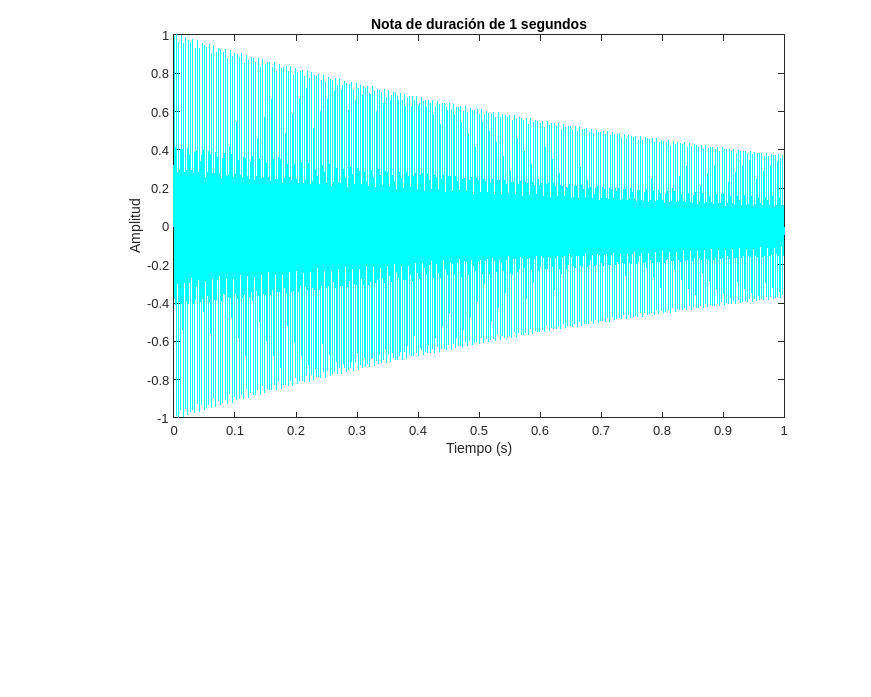

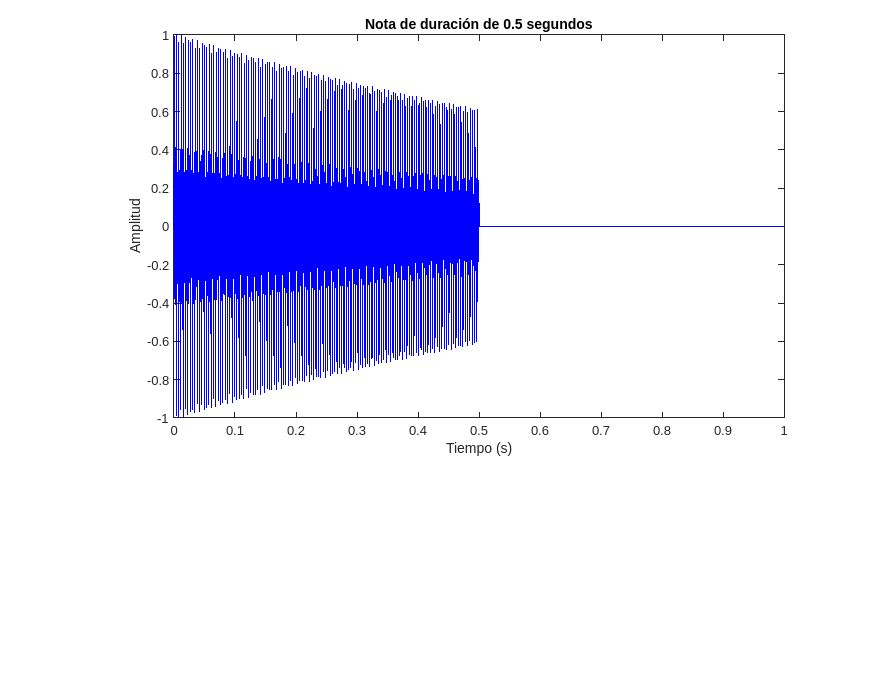

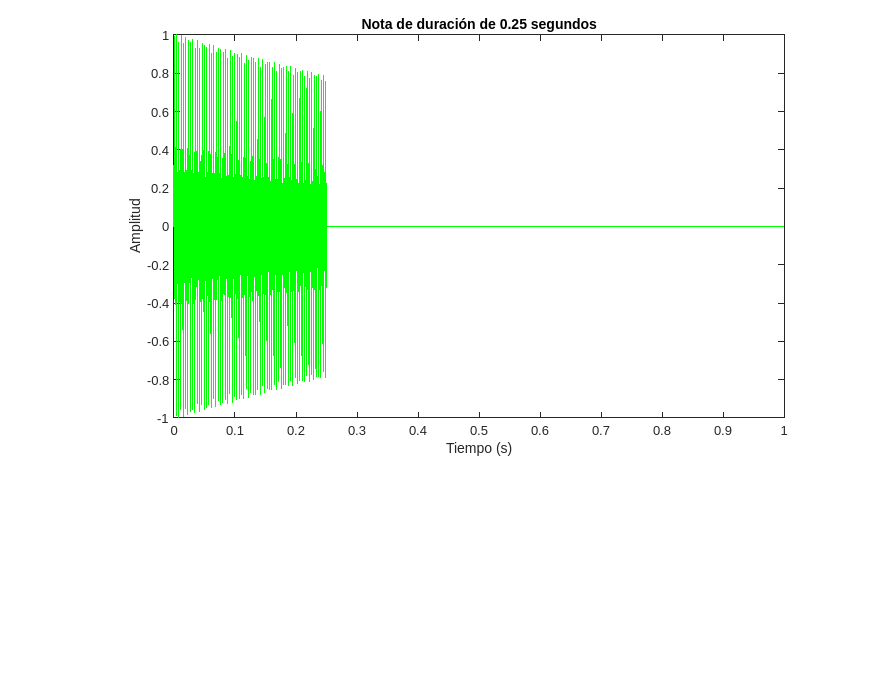

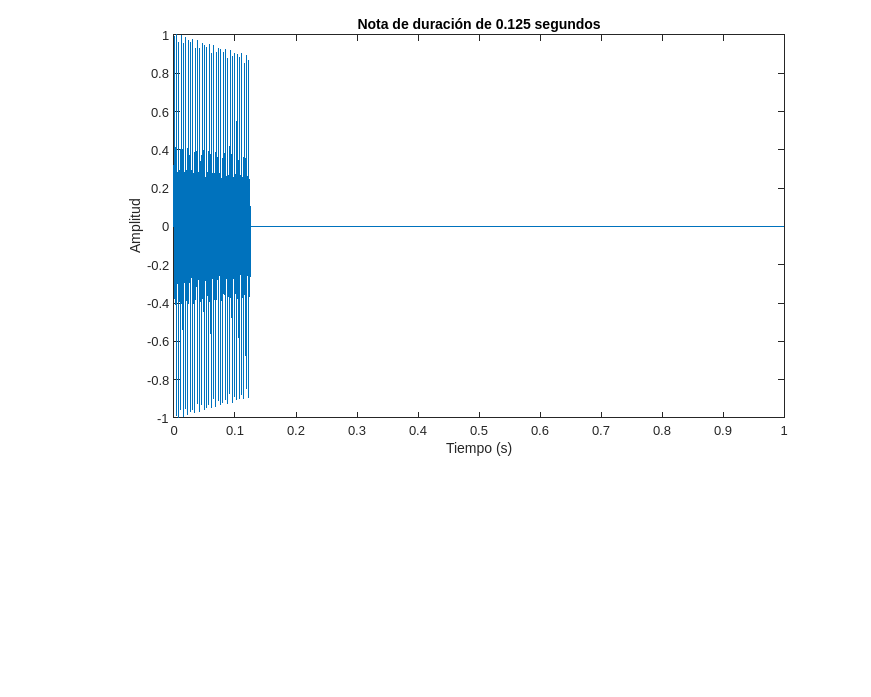

clear;
close all;


% Definimos las variables
TD = 1;                     % duración de la nota completa
nf = 261.63;                % frecuencia de C medio
nd = [1, 1/2, 1/4, 1/8];    % duración de la nota a reproducir
ns = 1;                     % amplitud de la nota

Fs = 8000;                  % frecuencia de muestreo en Hz
t = linspace(0, TD, Fs*TD); % vector de tiempos


% Envolvente
%env = ones(size(t));
tau = 1;                    % cte de tiempo que controla la rapidez con la que la envolvente decae
env = exp(-t/tau);          % envolvente exponencial

% Amplitud de los armónicos
ha = [1 2 3 4];

% Variables de instrumento
myinst();

count = 1;
color = {'c', 'b', 'g', ''};   

for i = 1:length(nd)

    n = mknote(nf, nd(i), ns, ha, env, t); % Genera la nota
    soundsc(n, 8000);                      % Reproduce la nota
    
    figure('Position',[0 0 1000 800])
    set(subplot(4,1,count),'Position',[0.2 0.4 0.7 0.55]);
    count = count + 1;
    plot(t, n, color{i});                  % Grafica la forma de onda de la nota
    xlabel('Tiempo (s)'); ylabel('Amplitud'); title(['Nota de duración de ' num2str(nd(i)) ' segundos']);
    pause(2);                              % Pausa para evitar solapamiento de notas

end

#### Vamos a tener en cuenta que este código ya está escrito con los ejemplos que nos piden en el numeral d) del punto 1 del taller.

# b). myinst.m

function [ha,env] = myinst()

    TD = 1;
    tau = 5;
    
    % Definir la amplitud de los armónicos
    ha = zeros(1, 20);

    % Define el envolvente de la nota
    t = linspace(0,TD,TD*8000);
    env = exp(-t/tau);
    %env = ones(size(t));
    env(t > TD) = 1;
    env(t < TD/2) = 0;

end

# c). mknote.m

function n = mknote(nf, nd, ns, ha, env, t)

    t2 = zeros(size(t));
    t2(1:nd*length(t)) = t(1:nd*length(t));
    
    harm = zeros(size(t));

    for i = 1:length(ha)
        harm = harm + ha(i)*sin(2*pi*i*nf*t2);
    end

    n = harm.*env;    
    n = ns*n/max(abs(n));

end

# d).

#### Podemos observar que los programas cumplen con lo que nos piden, se genera el sonido (C medio) para las diferentes duraciones, y las 4 gŕaficas anteriores muestran la nota para las duraciones de 1, 1/2, 1/4 y 1/8.

# e).

#### Una vez de haber realizado las diferentes pruebas, decidimos realizar un sonido de un piano crudo, para esto tomamos una amplitud de los armónicos moderados, es decir un sonido que contiene una cantidad moderada de armónicos en relación a la frecuencia fundamental. En otras palabras, no tiene un número extremadamente alto o bajo de armónicos. Y por el lado de la envolvente, nos decidimos por una envolvente exponencial (como se puede observar en el código). 